%simulink data for testing
Ts = 0.001

Ts = 1.0000e-03

Tsim = 120

Tsim = 120


F_c = 10;
W_c = 2*pi*F_c

W_c = 62.8319

Kd = 1/W_c

Kd = 0.0159

Kp = W_c^2/(sqrt(2))

Kp = 2.7915e+03

t = out.tout;
d = out.d_out.signals.values;
u = out.u_out.signals.values;
e = out.e_out.signals.values;
y = out.y_out.signals.values;



nfft = 2^10 ;
noverlap = nfft/2;
window = hann(nfft);
fs = 1/Ts

fs = 1000

fres = fs/nfft

fres = 0.9766

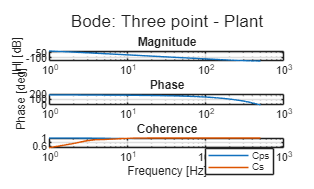


[f, H, S, C] = threePoint(d,e,u,window,noverlap,nfft,fs);
[~, l] = mybode(f,H,C,"Three point - Plant");
legend(l,'Cps','Cs');

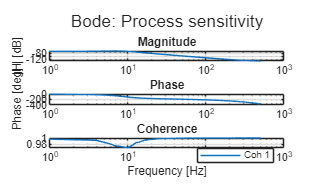

mybode(f,S(:,1),C(:,1),"Process sensitivity");

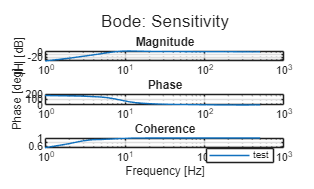

[~,l]= mybode(f,S(:,2),C(:,2),"Sensitivity");
legend(l,'test');

saveMeasurement(...
    struct("runtime", Tsim, "nfft", nfft, "noverlap", noverlap,"window", window, "fs", fs, "fres", fres), ...%settings
    struct("t",t,"d",d,"u",u,"e",e,"y",y), ... %signals
    struct("f",f,"H",H,"S",S,"C",C), ...%calculatedData
    'Measurements/3point/Testing');


% 
% function Data = isaveMeasurement(settings, signals, calculatedData, relativePath)
% Data.settings = settings;
% Data.signals = signals;
% Data.calculatedData = calculatedData;
% 
% [Path,fileName,~] = fileparts(relativePath);
% parts = strsplit(Path, filesep);
% Data.FileName = fileName;
% 
% 
% %go to folder -> create path if it does not exist yet
% % Build folder hierarchy step by step
% current = "";
% for i = 1:numel(parts)
%     current = fullfile(current, parts{i});
%     if ~isfolder(current)
%         mkdir(current);
%     end
% end
% 
% PathRaw = Path + "/Raw/";
% PathNumberd = Path + "/NumberdMeasurements/";
% if ~isfolder(PathRaw)
%         mkdir(PathRaw);
% end
% if ~isfolder(PathNumberd)
%     mkdir(PathNumberd);
% end
% 
% IndexPath = Path+"/MeasurementIndex.mat";
% storeIndex = 1;
% if isfile(IndexPath)
%     read = load(IndexPath);
%     storeIndex = read.storeIndex;
% else %create file
%     save(IndexPath,"storeIndex");
% end
% 
% Data.index = storeIndex;
% 
% %always save raw data with timestamp
% nowTime = now;  % current time
% timeMark = datestr(nowTime,'ddd_dd_mmm_HH') + "u" + ...
%            datestr(nowTime,'MM') + "m" + ...
%            datestr(nowTime,'SS') + "s";
% save(PathRaw + fileName + "_" + timeMark,"Data");
% 
% %save the numbered data
% save(PathNumberd +"/"+ storeIndex +"_"+ fileName,"Data");
% storeIndex = storeIndex +1;
% save(IndexPath,"storeIndex");
% 
% end
% 
% function [f, H, S, Coh] = ithreePoint(d,e,u,window,noverlap,nfft,fs)
% Coh = zeros(nfft/2+1,2);
% S = zeros(nfft/2+1,2);
% 
% %-PS e/d
% [PS_est,f_est] = tfestimate(d,-e,window,noverlap,nfft,fs);
% [Cps, ~] = mscohere(d,-e,window,noverlap,nfft,fs);
% S(:,1) = PS_est;
% Coh(:,1) = Cps;
% 
% %S u/d
% [S_est,~] = tfestimate(d,u,window,noverlap,nfft,fs);
% [Cs,~] = mscohere(d,u,window,noverlap,nfft,fs);
% S(:,2) = S_est;
% Coh(:,2) = Cs;
% 
% H_est = PS_est./S_est;
% H = H_est;
% f = f_est;
% end
% 
% function [fig, legend_tile] = imybode(f,H,C,fig_title)
%     fig = figure;
%     t = tiledlayout(3,1,"TileSpacing","tight");
%     title(t,'Bode: ' + fig_title);
% 
%     %Magnitude
%     nexttile
%     plot(f,20*log10(abs(H)));
%     xscale log; grid on;
%     %xlabel('Frequency [Hz]');
%     ylabel('|H| [dB]');
%     title('Magnitude');
% 
%     %Phase
%     nexttile
%     plot(f,rad2deg(unwrap(angle(H))));
%     xscale log; grid on;
%     %xlabel('Frequency [Hz]');
%     ylabel('Phase [deg]');
%     title('Phase');
% 
%     %Coherance
%     legend_tile = nexttile;
%     size_c = size(C);
%     for i = 1 : size_c(2)
%         semilogx(f,C(:,i)); hold on;
%     end
%     grid on;
%     title('Coherence');
%     xlabel('Frequency [Hz]');
%     legend(arrayfun(@(i) sprintf('Coh %d',i),1:size_c(2),'UniformOutput',false));
% end